% =========================================================================
% Standalone Classifier for Windowed EMG/Motion Features
% =========================================================================
% This script loads pre-extracted features and performs classification.
% 1. Loads the 'WindowedFeatures.mat' file.
% 2. Cleans the data, scales features, and performs simple selection.
% 3. Trains, cross-validates, and evaluates Random Forest, SVM, and
%    XGBoost-like (RUSBoost) classifiers.
% 4. Visualizes the most important features.
% =========================================================================

clear;
clc;

## Step 1: Load Pre-Extracted Features

fprintf('=== Step 1: Loading Windowed Features ===\n');

=== Step 1: Loading Windowed Features ===



% Check if the feature file exists
if ~exist('./Features/WindowedFeatures.mat', 'file')
    error('Feature file not found. Please run the feature extraction script first.');
end

% Load the .mat file containing the features and metadata
load('./Features/WindowedFeatures.mat');

% Extract data from the loaded structure
X_orig = windowed_features.features;
y_orig = windowed_features.labels;
feature_names = windowed_features.feature_names;
window_info = windowed_features.window_info;
class_names = windowed_features.class_names;

fprintf('✓ Loaded dataset from WindowedFeatures.mat\n');

✓ Loaded dataset from WindowedFeatures.mat


fprintf('Original dataset:\n');

Original dataset:


fprintf('  Total windows: %d\n', size(X_orig, 1));

  Total windows: 984


fprintf('  Features: %d\n', size(X_orig, 2));

  Features: 117



% Display class distribution from the loaded file
for i = 0:length(class_names)-1
    count = sum(y_orig == i);
    fprintf('  Class %d (%s): %d windows (%.1f%%)\n', i, class_names{i+1}, count, 100*count/length(y_orig));
end

  Class 0 (Chewing): 216 windows (22.0%)
  Class 1 (Swallowing): 539 windows (54.8%)
  Class 2 (Other): 229 windows (23.3%)


## Step 2: Basic Data Cleaning

fprintf('\n=== Step 2: Basic Data Cleaning ===\n');


=== Step 2: Basic Data Cleaning ===



X = X_orig;
y = y_orig;

% 1. Handle missing/infinite values
missing_count = sum(isnan(X(:)) | isinf(X(:)));
if missing_count > 0
    fprintf('Replacing %d missing/infinite values with 0\n', missing_count);
    X(isnan(X) | isinf(X)) = 0;
end

% 2. Remove constant features (no variation)
feature_vars = var(X);
constant_features = feature_vars < 1e-10;
n_constant = sum(constant_features);

if n_constant > 0
    fprintf('Removing %d constant features\n', n_constant);
    X = X(:, ~constant_features);
    feature_names_clean = feature_names(~constant_features);
else
    feature_names_clean = feature_names;
end

% 3. Feature scaling (standardization)
X_scaled = zscore(X);

fprintf('After cleaning: %d features remaining\n', size(X_scaled, 2));

After cleaning: 117 features remaining


## Step 3: Simple Feature Selection

fprintf('\n=== Step 3: Feature Selection ===\n');


=== Step 3: Feature Selection ===



% Remove features with very low variance (after scaling)
% This helps remove features that are nearly constant.
scaled_vars = var(X_scaled);
low_var_threshold = 0.1;
good_features = scaled_vars > low_var_threshold;

X_selected = X_scaled(:, good_features);
selected_feature_names = feature_names_clean(good_features);

fprintf('Selected %d features (removed %d low-variance features)\n', ...
    size(X_selected, 2), sum(~good_features));

Selected 117 features (removed 0 low-variance features)


## Step 4: Create Subject Mapping (for context, not used in k-fold)

fprintf('\n=== Step 4: Creating Subject Mapping ===\n');


=== Step 4: Creating Subject Mapping ===



subjects = {};
for i = 1:length(window_info)
    window_name = window_info{i};
    parts = strsplit(window_name, '_win_');
    segment_name = parts{1};
    subjects{end+1} = segment_name;
end
unique_subjects = unique(subjects);
n_subjects = length(unique_subjects);

fprintf('Found %d unique segments/subjects in the data.\n', n_subjects);

Found 7 unique segments/subjects in the data.


## Step 5: Cross-Validation

fprintf('\n=== Step 5: Cross-Validation ===\n');


=== Step 5: Cross-Validation ===



% Use simple k-fold instead of Leave-One-Subject-Out (LOSO) to avoid
% potential class imbalance issues within a single subject's data.
k_folds = 5;
cv_indices = crossvalind('Kfold', y, k_folds);

fprintf('Using %d-fold cross-validation\n', k_folds);

Using 5-fold cross-validation



% Initialize prediction arrays
rf_predictions = nan(size(y));
svm_predictions = nan(size(y));
xgb_predictions = nan(size(y)); % XGBoost predictions

for fold = 1:k_folds
    fprintf('Processing fold %d/%d...\n', fold, k_folds);
    
    test_mask = (cv_indices == fold);
    train_mask = ~test_mask;
    
    X_train = X_selected(train_mask, :);
    y_train = y(train_mask);
    X_test = X_selected(test_mask, :);
    
    fprintf('  Train: %d samples, Test: %d samples\n', sum(train_mask), sum(test_mask));
    
    train_classes = unique(y_train);
    fprintf('  Training set has classes: [%s]\n', num2str(train_classes'));
    
    % --- Random Forest Classifier ---
    try
        if length(train_classes) >= 2
            rf_model = TreeBagger(50, X_train, y_train, 'Method', 'classification', 'MinLeafSize', 2);
            rf_pred_labels = predict(rf_model, X_test);
            rf_predictions(test_mask) = str2double(rf_pred_labels);
            fprintf('  ✓ Random Forest completed\n');
        else
            fprintf('  ⚠ Random Forest skipped - insufficient classes\n');
            rf_predictions(test_mask) = mode(y_train);
        end
    catch ME
        fprintf('  ✗ Random Forest failed: %s\n', ME.message);
        rf_predictions(test_mask) = mode(y_train);
    end
    
    % --- SVM Classifier ---
    try
        if length(train_classes) >= 2
            svm_model = fitcecoc(X_train, y_train, 'Prior', 'uniform');
            svm_predictions(test_mask) = predict(svm_model, X_test);
            fprintf('  ✓ SVM completed\n');
        else
            fprintf('  ⚠ SVM skipped - insufficient classes\n');
            svm_predictions(test_mask) = mode(y_train);
        end
    catch ME
        fprintf('  ✗ SVM failed: %s\n', ME.message);
        svm_predictions(test_mask) = mode(y_train);
    end

    % --- XGBoost-like Classifier (RUSBoost) ---
    try
        if length(train_classes) >= 2
            % RUSBoost is good for imbalanced data, similar to XGBoost's strengths
            t = templateTree('MaxNumSplits', 5);
            rus_model = fitcensemble(X_train, y_train, 'Method', 'RUSBoost', 'Learners', t, 'NumLearningCycles', 50);
            xgb_predictions(test_mask) = predict(rus_model, X_test);
            fprintf('  ✓ RUSBoost (XGB) completed\n');
        else
            fprintf('  ⚠ RUSBoost (XGB) skipped - insufficient classes\n');
            xgb_predictions(test_mask) = mode(y_train);
        end
    catch ME
        fprintf('  ✗ RUSBoost (XGB) failed: %s\n', ME.message);
        xgb_predictions(test_mask) = mode(y_train);
    end
end

Processing fold 1/5...


  Train: 787 samples, Test: 197 samples


  Training set has classes: [0  1  2]


  ✓ Random Forest completed


  ✓ SVM completed


  ✓ RUSBoost (XGB) completed


Processing fold 2/5...


  Train: 786 samples, Test: 198 samples


  Training set has classes: [0  1  2]


  ✓ Random Forest completed


  ✓ SVM completed


  ✓ RUSBoost (XGB) completed


Processing fold 3/5...


  Train: 787 samples, Test: 197 samples


  Training set has classes: [0  1  2]


  ✓ Random Forest completed


  ✓ SVM completed


  ✓ RUSBoost (XGB) completed


Processing fold 4/5...


  Train: 788 samples, Test: 196 samples


  Training set has classes: [0  1  2]


  ✓ Random Forest completed


  ✓ SVM completed


  ✓ RUSBoost (XGB) completed


Processing fold 5/5...


  Train: 788 samples, Test: 196 samples


  Training set has classes: [0  1  2]


  ✓ Random Forest completed


  ✓ SVM completed


  ✓ RUSBoost (XGB) completed


## Step 6: Performance Evaluation

fprintf('\n=== Step 6: Performance Evaluation ===\n');


=== Step 6: Performance Evaluation ===



rf_valid = ~isnan(rf_predictions);
svm_valid = ~isnan(svm_predictions);
xgb_valid = ~isnan(xgb_predictions);

% Evaluate Random Forest
if sum(rf_valid) > 0
    fprintf('\n--- Random Forest Results ---\n');
    rf_acc = sum(y(rf_valid) == rf_predictions(rf_valid)) / sum(rf_valid);
    fprintf('Accuracy: %.3f (%.1f%%)\n', rf_acc, rf_acc*100);
    rf_cm = confusionmat(y(rf_valid), rf_predictions(rf_valid));
    fprintf('Confusion Matrix:\n'); disp(rf_cm);
end


--- Random Forest Results ---


Accuracy: 0.989 (98.9%)


Confusion Matrix:
   208     8     0
     1   538     0
     1     1   227




% Evaluate SVM
if sum(svm_valid) > 0
    fprintf('\n--- SVM Results ---\n');
    svm_acc = sum(y(svm_valid) == svm_predictions(svm_valid)) / sum(svm_valid);
    fprintf('Accuracy: %.3f (%.1f%%)\n', svm_acc, svm_acc*100);
    svm_cm = confusionmat(y(svm_valid), svm_predictions(svm_valid));
    fprintf('Confusion Matrix:\n'); disp(svm_cm);
end


--- SVM Results ---


Accuracy: 0.994 (99.4%)


Confusion Matrix:
   213     3     0
     0   539     0
     3     0   226




% Evaluate RUSBoost (XGB)
if sum(xgb_valid) > 0
    fprintf('\n--- RUSBoost (XGB-like) Results ---\n');
    xgb_acc = sum(y(xgb_valid) == xgb_predictions(xgb_valid)) / sum(xgb_valid);
    fprintf('Accuracy: %.3f (%.1f%%)\n', xgb_acc, xgb_acc*100);
    xgb_cm = confusionmat(y(xgb_valid), xgb_predictions(xgb_valid));
    fprintf('Confusion Matrix:\n'); disp(xgb_cm);
end


--- RUSBoost (XGB-like) Results ---


Accuracy: 0.917 (91.7%)


Confusion Matrix:
   188    20     8
    16   523     0
    26    12   191



## Step 7: Feature Importance Ranking

if sum(rf_valid) > 0
    fprintf('\n=== Step 7: Feature Importance Ranking ===\n');
    try
        % Train a final model on all data to get stable importance scores
        final_rf = TreeBagger(50, X_selected, y, 'Method', 'classification', 'OOBPrediction', 'on', 'OOBPredictorImportance', 'on');
        importance = final_rf.OOBPermutedPredictorDeltaError;
        [sorted_importance, sort_idx] = sort(importance, 'descend');
        
        fprintf('Top 20 most important features:\n');
        for i = 1:min(20, length(selected_feature_names))
            idx = sort_idx(i);
            fprintf('  %2d. %-40s (Importance: %.4f)\n', i, selected_feature_names{idx}, sorted_importance(i));
        end
    catch ME
        fprintf('Feature importance ranking failed: %s\n', ME.message);
        importance = []; % Ensure variable exists
    end
else
    importance = [];
end


=== Step 7: Feature Importance Ranking ===


Top 20 most important features:


   1. Motion_Mandible_Z_VelStd                 (Importance: 0.8846)
   2. Motion_Maxilla_X_VelStd                  (Importance: 0.8526)
   3. Motion_Maxilla_X_Std                     (Importance: 0.8297)
   4. Motion_Maxilla_X_Mean                    (Importance: 0.7277)
   5. Motion_Maxilla_Z_VelStd                  (Importance: 0.7067)
   6. Motion_ThyCart_Z_Max                     (Importance: 0.6501)
   7. Motion_Mandible_Y_RMS                    (Importance: 0.6404)
   8. Motion_Maxilla_X_RMS                     (Importance: 0.6120)
   9. Motion_Mandible_Y_Min                    (Importance: 0.6087)
  10. Motion_Maxilla_Z_Range                   (Importance: 0.6072)
  11. Motion_Maxilla_X_Min                     (Importance: 0.5814)
  12. Motion_Maxilla_X_Range                   (Importance: 0.5710)
  13. Motion_ThyCart_Z_Min                     (Importance: 0.5674)
  14. Motion_Mandible_Y_Mean                   (Importance: 0.5574)
  15. Motion_Mandible_Z_Range                  (

## Step 8: Feature Importance Visualization


=== Step 8: Visualizing Feature Importance ===


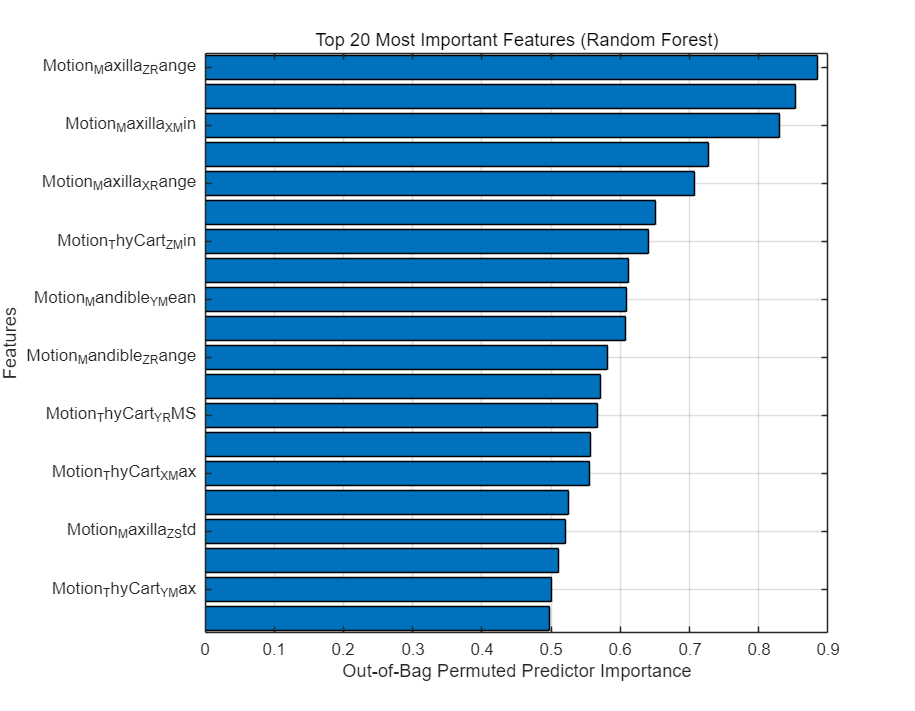

✓ Feature importance plot created.


if ~isempty(importance)
    fprintf('\n=== Step 8: Visualizing Feature Importance ===\n');
    
    try
        num_features_to_plot = 20;
        top_n = min(num_features_to_plot, length(sorted_importance));
        
        % Data for plotting (top N features)
        plot_importance = sorted_importance(1:top_n);
        plot_names = selected_feature_names(sort_idx(1:top_n));
        
        % Create a new figure for the plot
        figure('Name', 'Feature Importance', 'NumberTitle', 'off', 'Position', [100, 100, 900, 700]);
        
        % Use a horizontal bar chart
        barh(flip(plot_importance)); % Flip to have most important at the top
        
        % Set labels and title
        yticklabels(flip(plot_names));
        xlabel('Out-of-Bag Permuted Predictor Importance');
        ylabel('Features');
        title(sprintf('Top %d Most Important Features (Random Forest)', top_n));
        grid on;
        ylim([0.5, top_n + 0.5]); % Adjust y-axis limits
        
        fprintf('✓ Feature importance plot created.\n');
        
    catch ME
        fprintf('Feature importance visualization failed: %s\n', ME.message);
    end
end

## Step 9: Save Classification Results

fprintf('\n=== Step 9: Saving Classification Results ===\n');


=== Step 9: Saving Classification Results ===



results = struct();
results.rf_predictions = rf_predictions;
results.svm_predictions = svm_predictions;
results.xgb_predictions = xgb_predictions;
results.true_labels = y;
results.feature_names_selected = selected_feature_names;
results.class_names = class_names;
results.window_info = window_info;
if sum(rf_valid) > 0, results.rf_accuracy = rf_acc; end
if sum(svm_valid) > 0, results.svm_accuracy = svm_acc; end
if sum(xgb_valid) > 0, results.xgb_accuracy = xgb_acc; end


save('ClassifierResults.mat', 'results');
fprintf('✓ Results saved to ClassifierResults.mat\n');

✓ Results saved to ClassifierResults.mat


## Step 10: Final Summary

fprintf('\n=== Step 10: Summary ===\n');


=== Step 10: Summary ===


if sum(rf_valid) > 0
    fprintf('Final Random Forest Accuracy: %.1f%%\n', rf_acc*100);
end

Final Random Forest Accuracy: 98.9%


if sum(svm_valid) > 0
    fprintf('Final SVM Accuracy: %.1f%%\n', svm_acc*100);
end

Final SVM Accuracy: 99.4%


if sum(xgb_valid) > 0
    fprintf('Final RUSBoost (XGB-like) Accuracy: %.1f%%\n', xgb_acc*100);
end

Final RUSBoost (XGB-like) Accuracy: 91.7%


if sum(rf_valid) == 0 && sum(svm_valid) == 0 && sum(xgb_valid) == 0
    fprintf('⚠ WARNING: All classifiers failed to produce valid predictions.\n');
end